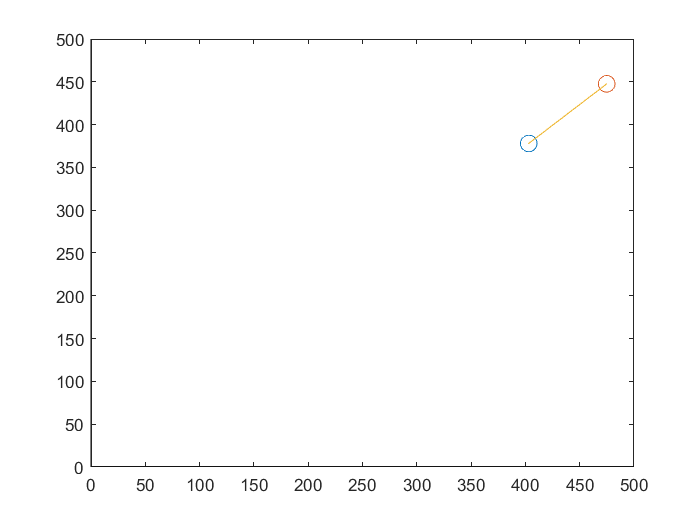

tspan = [0 40];
Y0 = [0 0 pi/4 0 0 -0.5];
[tSol,YSol] = ode45(@Q2ode,tspan,Y0);

% plot(tSol,YSol)
% 
% plot(tSol,YSol(:,3))

x1 = (YSol(:,1))/100;
y1 = (YSol(:,2))/100;

x2 = x1 + 100*cos(YSol(:,3));
y2 = y1 + 100*sin(YSol(:,3));

tstep = 0.001;
for k = 1:length(x1)
    
    plot(x1(k),y1(k),"o","markersize",10)
    hold on
    plot(x2(k),y2(k),"o","MarkerSize",10)
    hold on
    plot([x1(k) x2(k)],[y1(k) y2(k)])
    hold on

    %plotting X-axis
    plot([0 500],[0 0], "Color",'k')
    hold on 

    % Plotting Y-axis
    plot([0 0],[0 500],"Color",'k')
    hold off

    pause(tstep)
end

% figure
% P.l = 100;
% title('Question 2(i),Motion of a Ice Cart,Red is m1,Green is m2');
% %axis([0 1000 0 1000])
% hold on
% timestep = tRange(2)/length(YSol(:,1))
% for j = 1:length(tsol)
%    theta = YSol(j,3);
%    X = YSol(j,1);
%    Y = YSol(j,3);
%    xvals = [X X+P.l*cos(theta)];
%    yvals = [Y Y+P.l*sin(theta)];
%    plot(xvals,yvals,'k-','LineWidth',2)
%    plot(xvals(1),yvals(1),'ro','MarkerFaceColor','r','MarkerSize',10)
%    plot(xvals(2),yvals(2),'go','MarkerFaceColor','g','MarkerSize',10)
%    %drawnow
%    pause(0.2)
%    
% end
% hold off

function dYdt = Q2ode(t,Y)
%defining constants
m1 = 100;
m2 = 1;
l = 100;
Fx = 50;
Fy = 50;

Y1 = Y(1); %x
Y2 = Y(2); %y
Y3 = Y(3); %theta
Y4 = Y(4); %x.
Y5 = Y(5); %y.
Y6 = Y(6); %theta.

dY1dt = Y4;
dY2dt = Y5;
dY3dt = Y6;

A = [(m1+m2)*cos(Y3) (m1+m2)*sin(Y3) 0;-m2*l*sin(Y3) m2*l*cos(Y3) m2*(l^2);sin(Y3) -cos(Y3) 0];

B = [m2*l*(Y6^2) + Fx*l*cos(Y3) + Fy*l*sin(Y3);-Fx*l*sin(Y3) + Fy*l*cos(Y3);-Y4*Y6*cos(Y3)-Y5*Y6*sin(Y3)];

X = linsolve(A,B);

dY4dt = X(1);
dY5dt = X(2);
dY6dt = X(3);

dYdt =[dY1dt;dY2dt;dY3dt;dY4dt;dY5dt;dY6dt];
end